# Range-Doppler Response of FMCW Signal

Compute the range-Doppler response of an FMCW signal using an FFT.

Load data for an FMCW signal that has not been dechirped. The signal contains the return from a target about 2200 m away. The signal has a normalized Doppler frequency of approximately -0.36 relative to the radar.

load RangeDopplerExampleData;

Create a range-Doppler response object.

hrdresp = phased.RangeDopplerResponse(...
   'RangeMethod','FFT',...
   'PropagationSpeed',RangeDopplerEx_Dechirp_PropSpeed,...
   'SampleRate',RangeDopplerEx_Dechirp_Fs,...
   'DechirpInput',true,...
   'SweepSlope',RangeDopplerEx_Dechirp_SweepSlope);

Plot the range-Doppler response.

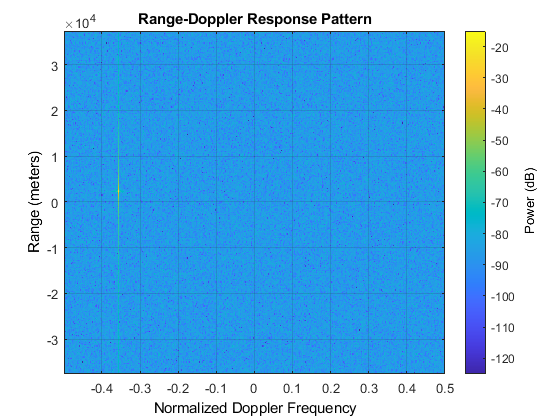

plotResponse(hrdresp,...
   RangeDopplerEx_Dechirp_X,RangeDopplerEx_Dechirp_Xref,...
   'Unit','db','NormalizeDoppler',true)

*Copyright 2015 The MathWorks, Inc.*